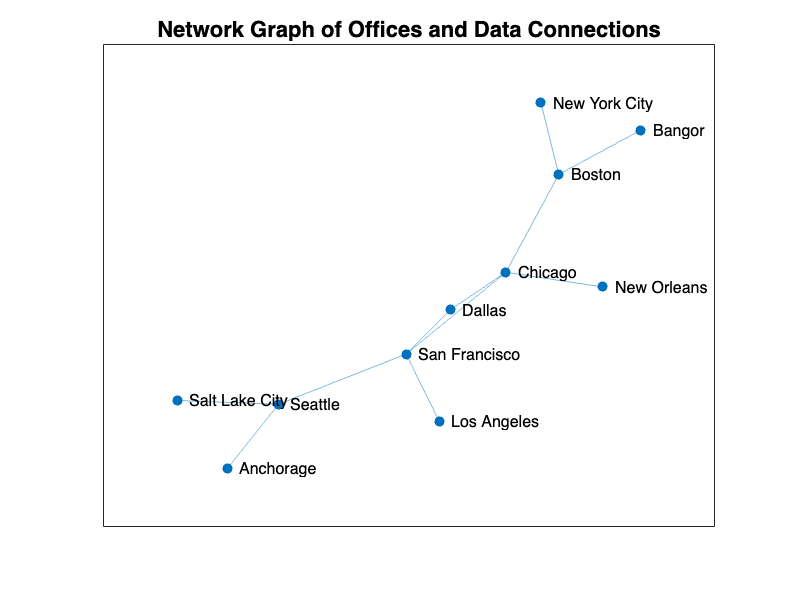

% Step 1: Define the adjacency matrix for the given network (symmetric version)
A = [0 1 0 0 0 0 0 0 0 0 0;
     1 0 1 1 0 0 0 0 0 0 0;
     0 1 0 0 0 0 0 0 0 0 0;
     0 1 0 0 1 1 1 0 0 0 0;
     0 0 0 1 0 0 0 0 0 0 0;
     0 0 0 1 0 0 1 1 0 1 0;
     0 0 0 1 0 1 0 0 0 0 0;
     0 0 0 0 0 1 0 0 0 0 0;
     0 0 0 0 0 0 0 0 0 1 0;
     0 0 0 0 0 1 0 0 1 0 1;
     0 0 0 0 0 0 0 0 0 1 0];

% Ensure the matrix is symmetric (undirected graph)
A = A + A';

% Step 2: Create the graph
G = graph(A);

% Step 3: Define the node labels (city names)
nodeLabels = {'Anchorage', 'Seattle', 'Salt Lake City', 'San Francisco', ...
              'Los Angeles', 'Chicago', 'Dallas', 'New Orleans', ...
              'New York City', 'Boston', 'Bangor'};

% Step 4: Plot the graph
figure;
plot(G, 'NodeLabel', nodeLabels);
title('Network Graph of Offices and Data Connections');


% Step 5: Find and display articulation points (critical nodes)
articulationPts = articulationpoints(G);

Unrecognized function or variable 'articulationpoints'.

disp('Articulation Points (critical nodes):');
disp(nodeLabels(articulationPts));

% Step 6: Find and display bridges (critical edges)
bridgeEdges = bridgemex(A);
disp('Bridge Edges (critical connections):');
disp(bridgeEdges);

% Step 7: Calculate and display betweenness centrality for nodes (security risks)
nodeBetweenness = centrality(G, 'betweenness');
disp('Betweenness Centrality of Nodes (higher values indicate higher risk):');
T = table(nodeLabels', nodeBetweenness, 'VariableNames', {'City', 'BetweennessCentrality'});
disp(T);

% Step 8: Max Flow Calculation
% Assume arbitrary weights for data transmission capacity (all 1s)
weights = ones(size(A));

% Calculate maximum flow from 'San Francisco' (node 5) to 'New York City' (node 8)
source = 5;  % San Francisco
sink = 8;    % New York City
maxFlowValue = maxflow(G, source, sink, 'Capacity', weights);
disp(['Maximum flow from San Francisco to New York City: ', num2str(maxFlowValue)]);